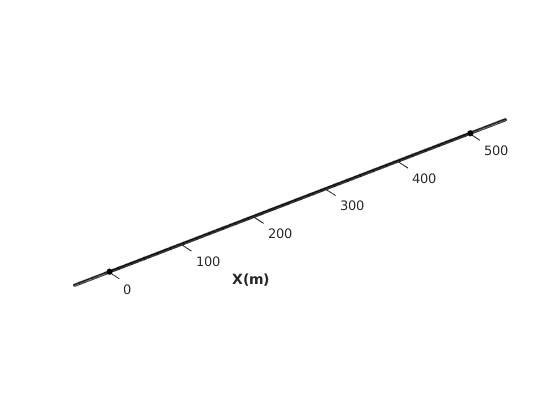

% Create a simulator object
sim = Sim();
% Disable Radar initialization, since this example uses
% a single lane on the ground
sim.en_init_radar = false;


% Define a single-lane LBSD object
lane_length_m = 500;
num_lanes = 1;
% lbsd = LBSD.genSimpleLanes(lane_length_m*ones(1,num_lanes));

lbsd = LBSD.genSimpleLanes([lane_length_m]);
plot(lbsd);

sim.lbsd = lbsd;

% Initialize the uas configuration
uas_config = UASConfig();
uas_config.num_uas = 100;
uas_config.setSpeedMix('CONSTANT',1)
uas_config.setHeadwayMix('CONSTANT',100)
uas_config.setFlexMix('CONSTANT',100)

sim.uas_config = uas_config;

% initialize the simulation configuration
sim_config = SimConfig();
sim_config.t0 = 0;
sim_config.tf = 2000;
sim_config.single_lane = "1";

sim.sim_config = sim_config;

figure;
% h_lbsd = lbsd.plot();
disp(lbsd.lane_graph.Nodes)

         XData    YData    ZData    Launch    Land    Name 
         _____    _____    _____    ______    ____    _____

    1       0       0        0        1        0      {'1'}
    2     500       0        0        0        1      {'2'}



disp(lbsd.lane_graph.Edges)

            EndNodes       Weight
         ______________    ______

    1    {'1'}    {'2'}     500  



sim.initialize(true);

Checking if LBSD is Instantiated
Initializing ATOC
Initializing UAS Dataset
Initializing UAS Trajectories
Updating Metrics
Done


Simulation Started


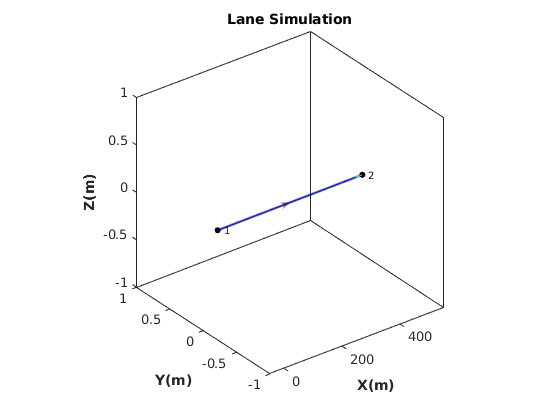

Simulation Complete


sim.run_sim()

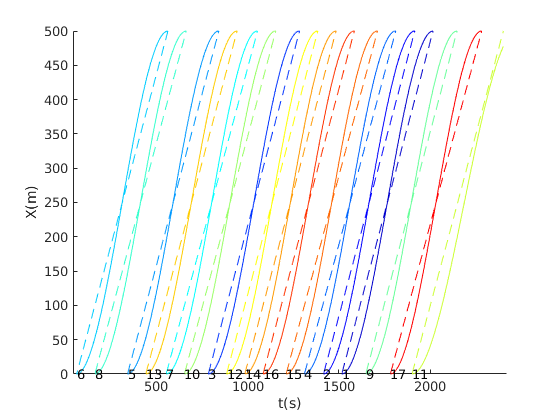

figure;
sim.plotTrajsX();

%lbsd.plotLaneDiagram("4");
min_hd = sim.getMaxXDeviation();
disp(["Max Deviation from Planned Trajectory = " min_hd])

    "Max Deviation from Planned Trajectory = "    "64.4539"



res = sim.lbsd.getReservations;
et = res.entry_time_s;
et = sort(et);
et_d = et(2:end)-et(1:end-1);
h_t = uas_config.hd_value/uas_config.speed_value;
all((et_d - h_t)>-100*eps)

ans = logical
   0


find((et_d - h_t)<-100*eps)

ans = 9

sim.sim_metrics.lane_occs

ans = struct with fields:
    lane_id: "1"
    num_uas: 17
        occ: 0.9000
